10.49

clc
close all
clear

mot.k = 5.2;
mot.T = 0.03;
Ts = 0.01;

s = tf('s');

Pc = mot.k / (s * (mot.T * s + 1));
Pd = c2d(Pc, Ts, "zoh");

z = tf('z', Ts);
s = (1 - z^-1) / Ts;
pid.Kp = 0.472;
pid.Kd = 0.016;
pid.Tl = 0.004;
C1 = pid.Kp;
C2 = minreal(pid.Kd * s / (pid.Tl * s + 1), 1e-6);

wc = 2 * pi * 5;
dl = 1 / sqrt(2);
H = minreal(wc^2 * s / (s^2 + 2 * dl * wc * s + wc^2), 1e-6);

C = minreal(C1 + C2, 1e-6);
T1 = minreal(feedback(C * Pd * H, 1), 1e-6);
G1 = minreal(Pd * H / (1 + Pd * H * C), 1e-6);
W1 = minreal(feedback(C, Pd * H), 1e-6);

rads2rpm = 60 / (2 * pi);
rpm2rads = 2 * pi / 60;

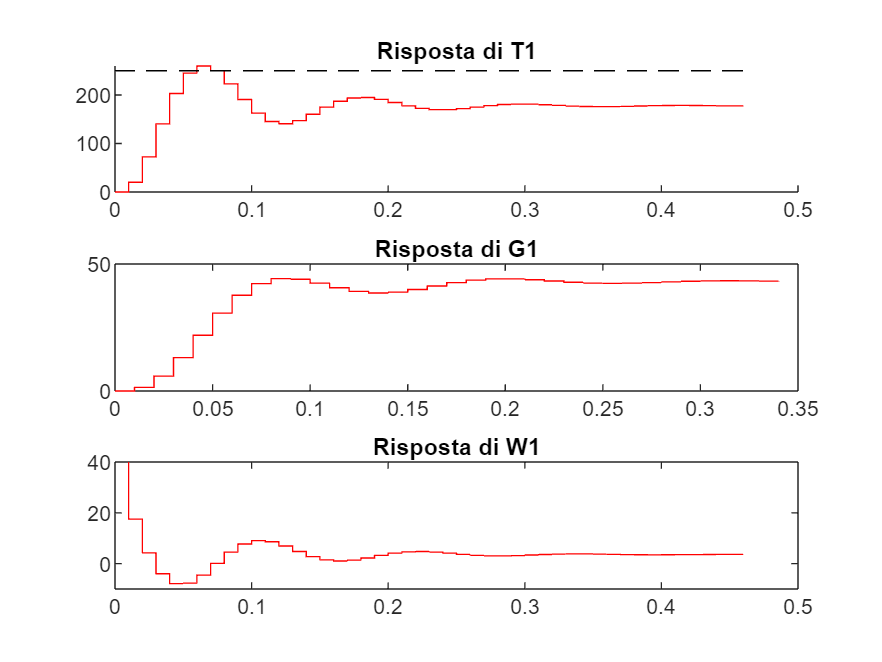

A = 250 * rpm2rads;
D = 3;
opt1 = stepDataOptions("StepAmplitude", A);
opt2 = stepDataOptions("StepAmplitude", D);
[yt1, tt1] = step(T1, opt1);
[yg1, tg1] = step(G1, opt2);
[yw1, tw1] = step(W1, opt1);

close all
figure(1)
subplot(3, 1, 1)
hold on
stairs(tt1, yt1 * rads2rpm, "r")
plot([tt1(1), tt1(end)], [250 250], "k--")
title("Risposta di T1")

subplot(3, 1, 2)
stairs(tg1, yg1 * rads2rpm, "r")
title("Risposta di G1")

subplot(3, 1, 3)
stairs(tw1, yw1, "r")
ylim([-10 40])
title("Risposta di W1")

T2 = minreal(Pd * H * C1 / (1 + Pd * H * (C1 + C2)), 1e-6);
G2 = minreal(Pd * H / (1 + Pd * H * (C1 + C2)), 1e-6);
W2 = minreal(C1 / (1 + Pd * H * (C1 + C2)), 1e-6);

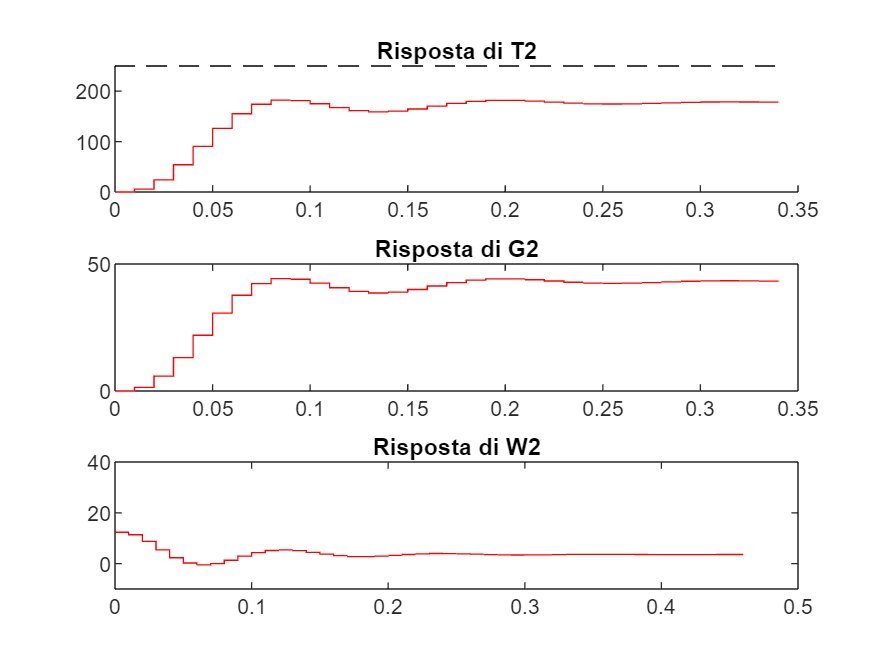

[yt2, tt2] = step(T2, opt1);
[yg2, tg2] = step(G2, opt2);
[yw2, tw2] = step(W2, opt1);

close all
figure(2)
subplot(3, 1, 1)
hold on
stairs(tt2, yt2 * rads2rpm, "r")
plot([tt2(1), tt2(end)], [250 250], "k--")
title("Risposta di T2")

subplot(3, 1, 2)
stairs(tg2, yg2 * rads2rpm, "r")
title("Risposta di G2")

subplot(3, 1, 3)
stairs(tw2, yw2, "r")
ylim([-10 40])
title("Risposta di W2")

Confrontando i grafici relativi alla risposta dei sistemi W, si nota come per W1 ci sia inizialmente un picco di tensione in corrispondenza di un segnale discontinuo, in questo caso un gradino, mentre W2 è privo di questo picco.

11.10